# *'*Surface*'* method usage example

#### Add *povlab* to path

if isunix
    addpath ("/home/serge/projects/povlab");
elseif ispc
    addpath ("C:/Users/Serge/Documents/MATLAB/Apps/povlab");
else
    disp('Platform not supported')
end


#### Total clean up

clear;
clear povlab;
close all;

#### Start time measurement

tic % Time measure

#### Create *povlab *object and init it with version and path to *POVRAY* that installed in your system, set images output directory

if isunix
pl = povlab( "3.7",...
             '"/usr/local/bin/povray +A -W1920 -H1080 -L/home/serge/projects/povlab/include -L/home/serge/projects/povlab/examples/out"', ...
             "/home/serge/projects/povlab/examples/out");
elseif ispc
    pl = povlab( "3.7",...
                 "C:/Program Files/POV-Ray/v3.7/bin/pvengine64.exe", ...
                 "C:/Users/Serge/Documents/MATLAB/Apps/povlab/examples/out");
else
    disp('Platform not supported')
end


#### Create *camera* object and put it in separate include file to save rendering time

pl.include_begin('camera');
    % Camera
    % type: perspective | orthographic | mesh_camera{MESHCAM_MODIFIERS} | fisheye | ultra_wide_angle |
    %       omnimax | panoramic | cylinder CylinderType (<int[1..4]>) | spherical
    %pl.camera();
    pl.camera('angle', 45, 'location', [-10 -14 7], 'look_at', [0 0 0], 'type', 'perspective');
    
    % pl.camera('angle', 35, 'location', [12 12 5], 'look_at', [0 1 0]);
    % pl.camera('location', [12 12 12], 'look_at', [0 1 0]);
    % pl.camera('angle', 35, 'look_at', [0 1 0]);
    % pl.camera("angle", 15, 'location', [12 12 12]);
pl.include_end();

#### Create *lights* objects and put them in separate include file to save rendering time

% Light
pl.include_begin('lights');
    % pl.light();
    pl.light('location', [-10 -17 7], 'color', [1 1 1], 'shadowless', true);
    % pl.light('location', [10 -10 30],  'color', [0.8 0.8 0.8], 'shadowless', true);
    pl.light('location', [-10 10 30],  'color', [0.8 0.8 0.8], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [0.4 0.4 0.4], 'shadowless', true);
pl.include_end();

#### Create supplemental helpers objects objects and put them in separate include file to save rendering time

% Helpers
pl.include_begin('helpers');
    % Axis textures
    tex_axis_gray = pl.declare("tex_axis_gray", pl.texture('pigment', [0.5 0.5 0.5], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    tex_axis_yellow = pl.declare("tex_axis_yellow", pl.texture('pigment', [1.0 1.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    % tex_axis_x = pl.declare("tex_axis_x", pl.texture('pigment', [1 1 1], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    % tex_axis_y = pl.declare("tex_axis_y", pl.texture('pigment', [0 1 0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    % tex_axis_z = pl.declare("tex_axis_z", pl.texture('pigment', [0 0 1], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    
    % Axis
    % pl.axis();
    % pl.axis('length', [5 5 4], 'radius', 0.07);
    pl.axis('length', [10 10 10], 'tex_common', tex_axis_gray, 'tex_x', tex_axis_yellow, 'tex_y', tex_axis_yellow, 'tex_z', tex_axis_yellow);
    
    % Grid
    % tex_grid_gray  = pl.declare("tex_grid_gray",  pl.texture('pigment', [0.5 0.5 0.5], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    % tex_grid_red   = pl.declare("tex_grid_red",   pl.texture('pigment', [1.0 0.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    % tex_grid_green = pl.declare("tex_grid_green", pl.texture('pigment', [0.0 1.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    % tex_grid_blue  = pl.declare("tex_grid_blue",  pl.texture('pigment', [0.0 0.0 1.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    
    pl.grid('width', 10, 'height', 10);
    %pl.grid_2D('width', 10, 'height', 10,                      'translate', [5 0 5], 'texture_odd', tex_grid_green, 'texture_even', tex_grid_gray);
    % pl.grid_2D('width', 10, 'height', 10, 'rotate', [ 0 0 90], 'translate', [0 5 5], 'texture_odd', tex_grid_blue,  'texture_even', tex_grid_gray);
    % pl.grid_2D('width', 10, 'height', 10, 'rotate', [90 0  0], 'translate', [5 5 0], 'texture_odd', tex_grid_red,   'texture_even', tex_grid_gray);
    
    % pl.grid_2D('width', 10, 'height', 10,                      'translate', [5 0 5]);
    % pl.grid_2D('width', 10, 'height', 10, 'rotate', [ 0 0 90], 'translate', [0 5 5]);
    % pl.grid_2D('width', 20, 'height', 20, 'rotate', [90 0  0], 'translate', [0 0 0]);

    % Axis planes textures
    % tex_plane_red   = pl.declare("tex_plane_red",   pl.texture('pigment', [0.8 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    % tex_plane_green = pl.declare("tex_plane_green", pl.texture('pigment', [0.3 0.8 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    % tex_plane_blue  = pl.declare("tex_plane_blue",  pl.texture('pigment', [0.3 0.3 0.8], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    
    tex_plane_red   = pl.declare("tex_plane_red",   pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    tex_plane_green = pl.declare("tex_plane_green", pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.0 metallic 0.0}"));
    tex_plane_blue  = pl.declare("tex_plane_blue",  pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
    
    % Axis planes
    % pl.plane('normal', [1,0,0], 'distance', 0, 'texture', tex_plane_red',  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
    % pl.plane('normal', [0,1,0], 'distance', 0, 'texture', tex_plane_green, 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
    % pl.plane('normal', [0,0,1], 'distance', 0, 'texture', tex_plane_blue,  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
pl.include_end();


#### Open the *POVRAY* scene, include previousely created obects and fill it with content

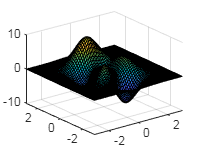

s =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [60×60 double]
           YData: [60×60 double]
           ZData: [60×60 double]
           CData: [60×60 double]

  Show all properties


pl.scene_begin('scene_file', 'mesh.pov', 'image_file', 'mesh.png');
    pl.include("camera");
    pl.include("lights");
    pl.include("helpers");
    pl.include("textures");
    
    pl.global_settings("assumed_gamma 1");
    
    % pl.raw(['sky_sphere{ pigment{ gradient <0,1,0> '...
    %                      'color_map{ [0   color rgb<1,1, 1>       ] '...
    %                                 '[0.4 color rgb<0.1, 0.1, 0.1>] '...
    %                                 '[0.8 color rgb<0.2, 0.2, 0.2>]  '...
    %                                 '[1.0 color rgb<0.7,0.7,0.7>  ]} '...
    %                      'scale 2  }}']);
    
    % pl.light('location', [100 0 0], 'color', [0.1 0.1 0.1]);
    % pl.light('location', [0 100 0], 'color', [0.1 0.1 0.1]);
    % pl.light('location', [0 0 100], 'color', [0.1 0.1 0.1]);
    
    % Objects textures
    % tex_red   = pl.declare("tex_red",   pl.texture('pigment', [1 0 0], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
    % tex_green = pl.declare("tex_green", pl.texture('pigment', [0 1 0], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
    % tex_blue  = pl.declare("tex_blue",  pl.texture('pigment', [0 0 1], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
    % tex_pink  = pl.declare("tex_pink",  pl.texture('pigment', [8 2 3], 'finish', 'phong 1 reflection {0.10 metallic 0.4}'));
    
    size = 60;
    % f = figure('Visible', 'off');
    [X,Y,Z] = peaks(size);
    s = surf(X,Y,Z)

    
    % x = -2:0.1:2;
    % y = 1:0.1:2;
    % [X,Y] = meshgrid(x,y);
    % Z = peaks(X,Y);
    % s = surf(X,Y,Z);
    
    % x = -2:0.5:2;
    % y = 1:0.2:2;
    % [X,Y] = meshgrid(x,y);
    % Z = peaks(X,Y);
    % s = surf(X,Y,Z);
    
    % [X,Y] = meshgrid(1:0.5:10,1:20);
    % % Z = sin(X) + cos(Y);
    % C = X.*Y;
    % s = surf(X,Y,Z)
    % s = surf(X,Y,Z,C)
    
    % -- Textures --
    % DMFWood6
    % NBglass            (Norm Bowler)
    % NBoldglass         (Norm Bowler)
    % NBwinebottle       (Norm Bowler)
    % NBbeerbottle       (Norm Bowler)
    % Ruby_Glass         (after Norm Bowler)
    % Dark_Green_Glass   (after Norm Bowler)
    % Yellow_Glass       (after Norm Bowler)
    % Orange_Glass       (after Norm Bowler)
    % Vicks_Bottle_Glass (after Norm Bowler)
    % Soft_Silver        (Dan Farmer)
    % New_Penny          (Dan Farmer)
    % Tinny_Brass        (Dan Farmer)
    % Gold_Nugget        (Dan Farmer)
    % Aluminum           (Dan Farmer)
    % Bright_Bronze      (Dan Farmer)
    % Lightening1        (Dan Farmer)
    % Lightening2        (Dan Farmer)
    % Brushed_Aluminum   (Dan Farmer)
    % Starfield          (Jeff Burton )
    % Shadow_Clouds      (Bill Pulver)
    % pl.mesh('surface', s, 'rotate', [90, 0, 0]);
    % pl.mesh('surface', s, 'rotate', [90, 0, 0], 'texture', 'Dark_Green_Glass');
    % pl.mesh('surface', s, 'texture_odd', 'Dark_Green_Glass', 'texture_even', 'Aluminum', 'smooth', true, 'rotate', [90, 0, 0], 'scale', [1.5, 1.5, 1.5]);
    % pl.mesh('surface', s, 'texture_odd', 'Ruby_Glass', 'texture_even', 'Aluminum', 'smooth', true, 'rotate', [90, 0, 0], 'scale', [1.5, 1.5, 1.5]);
    
    pl.surface('surface', s, 'smooth', false, 'colormap', 'turbo', 'scale', [1, 1, 3/10], 'texture_odd', 'Aluminum', 'texture_even', 'Dark_Green_Glass');
    
    % pl.difference_begin();
    %     %pl.sphere();
    %     pl.sphere('position', [1 1 1], 'radius', 2, 'texture', tex_green, 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 1 0]);
    %     pl.union_begin();
    %           pl.sphere('position', [2 1 2], 'radius', 0.7, 'texture', tex_red,  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
    %           pl.sphere('position', [2 3 1], 'radius', 0.8, 'texture', tex_blue, 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
    %           pl.sphere('position', [1 2 3], 'radius', 1.0, 'texture', tex_pink, 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
    %      pl.union_end('translate', [0.3 0.3 0.3]);
    % pl.difference_end('scale', [1 1 1], 'rotate', [0 0 0], 'translate', [3 3 4]);

#### Close *POVRAY* scene

pl.scene_end();

#### Render scene and show rendered image

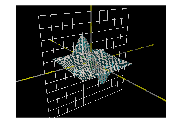

image = pl.render();
imshow(image);

#### Display elapsed time

toc % Elapsed time

Elapsed time is 4.318450 seconds.
